## Строю несколько класификаторов для каждой ноты

clear all
close all

path = "D:\Desktop\Studie\Diploma\GIT Matlab\Audio data\wav";
path1 = path + "\Sasha\Steinway Grand Piano 70.wav";
[y, Fs] = audioread(path1);
z = y(:,1);

NOTES = 84;
Tab_F_1 = [65.41  69.3  73.42  77.78  82.41  87.31  92.5  98  103.83  110  116.54  123.47];
k = 2.^(0:6) / 2;
Tab_F = k' .* repmat(Tab_F_1, 7, 1);
M = zeros(7, 12);
Ms = M;

NFFT = 1024;
N_zero = Fs - NFFT;     % Кол-во нулей после вырезки. Я буде для частотного шага 1Гц
N = floor(2/(NFFT/Fs)); % Количество вырезок за 2 секунды
ds = 11;                % В сколько раз уменьшить спектр. Минимум 2 - нормально

data = reshape(z,4*Fs,[]);  % Каждая нота отдельно
data = data(1:N*NFFT, :);   % Каждая нота отдельно Без нулей
data = data(:, 1:87);       % Откидываем 5тую октаву ноту До
data = data(:,4:end);       % Откидываю первые 3 ноты суб-контр октавы

Y = zeros(N*NOTES, 1);
X = zeros([N*NOTES, NFFT+N_zero]);    % С интерполяцией
% X = zeros([N*NOTES, NFFT]);         % Без интерполяции

h = hamming(NFFT)';
for k=1:NOTES
    
    N1 = N * (k-1) + 1;
    N2 = N1 + N - 1;
    notes = reshape(data(:,k),NFFT,[])';
    
    % Add Hamming window
    notes = notes .* h;
    
    X(N1:N2, 1:NFFT) = notes;
    Y(N1:N2) = k;
    
end

clear N1 N2 h

cv = cvpartition(Y,'HoldOut',0.30);
trainInds = training(cv);
testInds = test(cv);

XTrain = X(trainInds,:);
YTrain = Y(trainInds);
XTest = X(testInds,:);
YTest = Y(testInds);

clear z X Y y

[STest, MTest] = size(XTest);
[STrain, MTrain] = size(XTrain);

vtest = floor(1:MTest/ds);
vtrain = floor(1:MTrain/ds);

XTest_ds = zeros([STest, length(vtest)]);
XTrain_ds = zeros([STrain, length(vtrain)]);

% Get Spectrum. There is no need to get whole spectrum, It can be divided
% by half or more. ds - specifies how spectrum will be divided.
XTest_spec = abs(fft(XTest'))';
XTrain_spec = abs(fft(XTrain'))';

% Get only one part of spectrum, only important samples
XTest_ds(:, vtest) = XTest_spec(:, vtest);
XTrain_ds(:, vtest) = XTrain_spec(:, vtest);

% Normalization of data
XTest_ds  = XTest_ds ./ sum(XTest_ds, 2);
XTrain_ds = XTrain_ds ./ sum(XTrain_ds, 2);

clear XTrain XTest XTest_spec XTrain_spec MTest MTrain

Class_per_Note = 2;         % Number of classes for each note
rest_num = 60 - Class_per_Note*floor(60/Class_per_Note);

if rest_num > 0
    Class_per_Note = Class_per_Note + 1;
end

mean_M = zeros([NOTES Class_per_Note 7 12]);
std_M  = zeros([NOTES Class_per_Note 7 12]);

Indexes = floor(Tab_F);   % NOT FLAT!!!
v1 = [1 1 1 1 1 1 1 ] * 1/7;
v2 = [0 1 1 1 1 1 1 ] * 1/6;
v3 = [0 0 1 1 1 1 1 ] * 1/5;
v4 = [0 0 0 1 1 1 1 ] * 1/4;
v5 = [0 0 0 0 1 1 1 ] * 1/3; 
v6 = [0 0 0 0 0 1 1 ] * 1/2;
v7 = [0 0 0 0 0 0 1 ];
V = [v1; v2; v3; v4; v5; v6; v7];
clear path y Tab_F_1 k v1 v2 v3 v4 v5 v6 v7

% i = number of note
for i = 1:NOTES

    ind = find(YTrain==i); 
    X_note = XTrain_ds(ind, :);
    
    Ncuts = length(ind);
    
    cnt = 1;
    for j = 1:Class_per_Note
        
        % Define how many cuts will be used for
        % finding Gauss parameters for single classifier
        if j == Class_per_Note && rest_num > 0
            n = rest_num;
        else
            n = floor(60/Class_per_Note);
        end
        
        temp_M = zeros([n 7 12]);
        
        while n > 0
            
            x = X_note(cnt, :);    % Current signal
            
            M = x(Indexes);          % Заполняем матрицу нот
            Ms = V * M;
            
            temp_M(n, :, :) = Ms;
            
            cnt = cnt + 1;
            n = n - 1;
        end
        
        mean_M(i, j, :, :) = mean(temp_M, 1);
        std_M (i, j, :, :) = std(temp_M, 1);
        
    end
    
end



p_error    = 0;
my_notes   = zeros([STest 1]);
true_notes = zeros([STest 1]);

tic
for j = 1:STest
    
    test_sig = XTest_ds(j, :);
    test_label = YTest(j);

    M = test_sig(Indexes);          % Заполняем матрицу нот
    Ms = V * M;
    
    Prob_note = ones([NOTES, Class_per_Note]);
    
    % i = number of note
    for i = 1:NOTES
        
        for jj = 1:Class_per_Note
            
            % k = single sample of Ms
            for k = 1:(7*12)
                
                m = Ms(k);
                std_cur  = std_M (i, jj, k);  % Current std
                mean_cur = mean_M(i, jj, k);  % Current mean
                
                if std_cur == 0 && k > 1
                    std_cur = std_M (i, jj, k-1);
                end
                
                if abs(m-mean_cur) > 3*std_cur
                    p = 0.001;
                else
                    p = gaussmf(m, [std_cur mean_cur]);
                end
        
                Prob_note(i, jj) = Prob_note(i, jj) * p;
            end
            
        end
        
    end
    
    note = mod(find(Prob_note==max(max(Prob_note))), NOTES);
    
    if note ~= test_label
        p_error = p_error + 1;
    end
    
    my_notes(j) = note(1);% Sometimes it returns 1x88 zeros vector  
    true_notes(j) = test_label;
    
end
toc

Elapsed time is 112.500898 seconds.


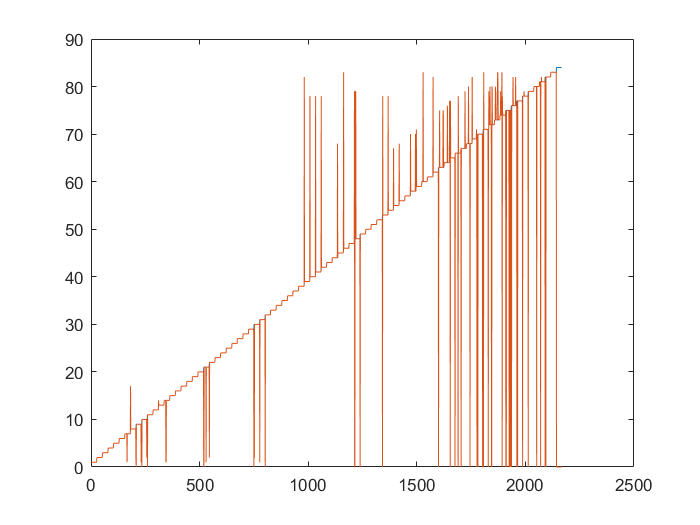


figure
plot(true_notes)
hold on
plot(my_notes)
hold off


p_error = 100 * p_error / STest

p_error = 6.3221

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Number of classes  |  Error rate
% 1                  |  3.7
% 2                  | 6.3 - 5.6 log (8.6 -- /max) (9.4 -- /sum)
% 3                  |  5.7 log
% 6                  |  5.7 log
% 10                 |  6.6 log